# 7.3 Optimum filters

Alexandre Rey, MSE, Ma-StatDig, 2022

clear;
rng default;

importedData = load('ex73_data.mat');

## Ex7.3 : FIR Wiener - Noise Cancellation (7.2.6)

On a $x[n]$ et on aimerait supprimer $v_1[n]$, on peut mesurer une image de $v[n]$ avec $v_2[n]$.

The noise cancellation problem is described by the following figure:

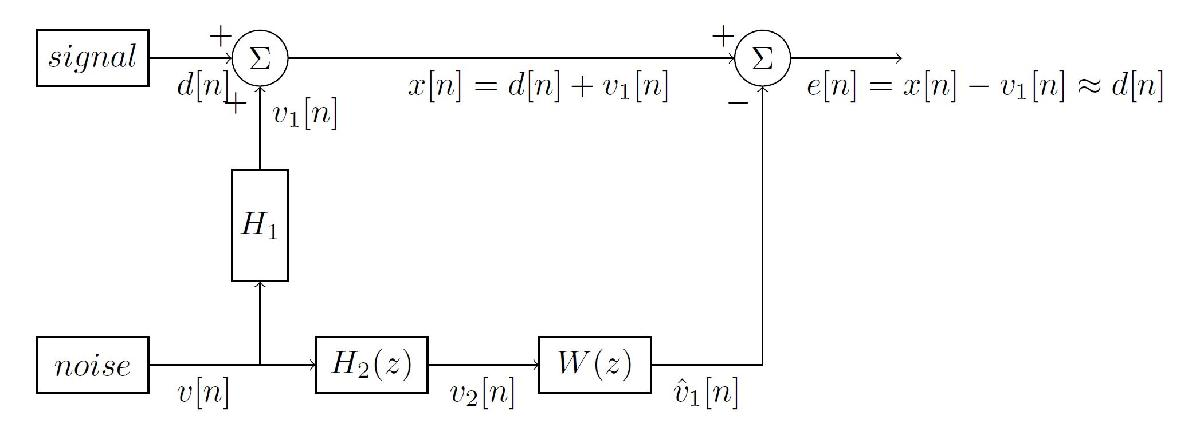

Suppose the desired signal $d[n]$ is given by :


$$d\left\lbrack n\right\rbrack =\sin \left(n\omega_0 +\phi \;\right)$$


with $\omega_0 = 0.05\pi$and the related noise sequence$v_1[n]$ and $v_2[n]$ are AR(1) processes driven by the same noise signal $v[n]$.


$$v_1 \left\lbrack n\right\rbrack =0\ldotp 8v_1 \left\lbrack n-1\right\rbrack +v\left\lbrack n\right\rbrack$$



$$H_1 \left(z\right)=\frac{1}{1-0\ldotp 8z^{-1} }$$



$$v_2 \left\lbrack n\right\rbrack =-0\ldotp 6v_2 \left\lbrack n-1\right\rbrack +v\left\lbrack n\right\rbrack$$



$$H_2 \left(z\right)=\frac{1}{1+0\ldotp 6z^{-1} }$$


Where $v[n]$ is zero-mean, unit variance white noise that is clearly uncorrelated with $d[n]$.

Goal is to design a FIR Wiener filter of orders 6 and 12 to remove the noise.

## Signals creation

### Parameters

SigmaN = 1;
N = 200;
p = [6 12];
H1_a = -0.8;
H2_a = 0.6;

disp(table(SigmaN, N, p, H1_a, H2_a));

    SigmaN     N        p       H1_a    H2_a
    ______    ___    _______    ____    ____

      1       200    6    12    -0.8    0.6 



## Signal generation

Based on the previous parameters, the signals are generated.

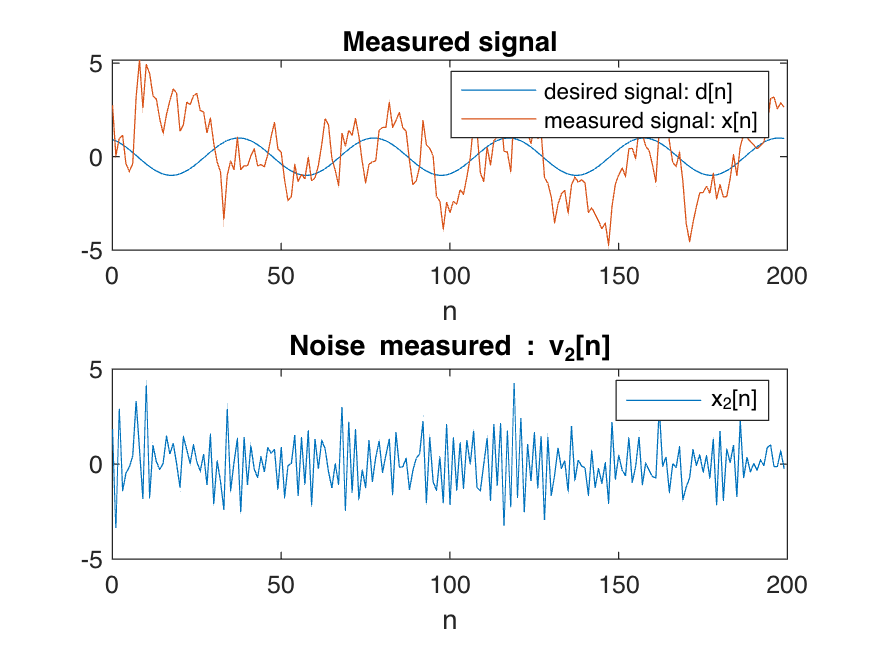

n = 0:N-1;
omega0 = 0.05*pi;
%dn = sin(n.*omega0 + phi);
% we don't know phy which is random so we take signal of the teacher
dn = importedData.d;   % signal without noise we try to find
xn = importedData.x;   % signal measured
v2 = importedData.v2;  % noise measured

figure;
subplot(2,1,1);
    plot(n, dn, ...
         n, xn);
    title('Measured signal');
    legend('desired signal: d[n]','measured signal: x[n]');
    xlabel('n');
subplot(2,1,2);
    plot(n, v2);
    title('Noise measured : v_2[n]');
    legend('x_2[n]');
    xlabel('n');

## Wiener solving

### Filter design

The Wiener-Hopf equations for the noise cancellation described by figure are given by :


$${\mathit{\mathbf{R}}}_{v_2 ,v_2 } \mathit{\mathbf{w}}={\mathit{\mathbf{r}}}_{v_1 ,v_2 }$$


As we assume that the noise $v_2[n]$ is uncorrelated with $d[n]$:


$$r_{v_1 ,v_2 } \left\lbrack k\right\rbrack =E\left\lbrace v_1 \left\lbrack n\right\rbrack {v_2 }^* \left\lbrack n-k\right\rbrack \right\rbrace =E\left\lbrace \left\lbrack x\left\lbrack n\right\rbrack -d\left\lbrack n\right\rbrack \right\rbrack {v_2 }^* \left\lbrack n-k\right\rbrack \right\rbrace =E\left\lbrace x\left\lbrack n\right\rbrack v_2 \left\lbrack n-k\right\rbrack \right\rbrace$$


Then, the Wiener-Hopf equations become:


$${\mathit{\mathbf{R}}}_{v_2 ,v_2 } \mathit{\mathbf{w}}={\mathit{\mathbf{r}}}_{x,v_2 }$$


And the solution is:


$$\mathit{\mathbf{w}}={\mathit{\mathbf{R}}}_{v_2 ,v_2 }^{-1} {\mathit{\mathbf{r}}}_{x,v_2 }$$


The different correlation and cross-correlation are (for two different orders):

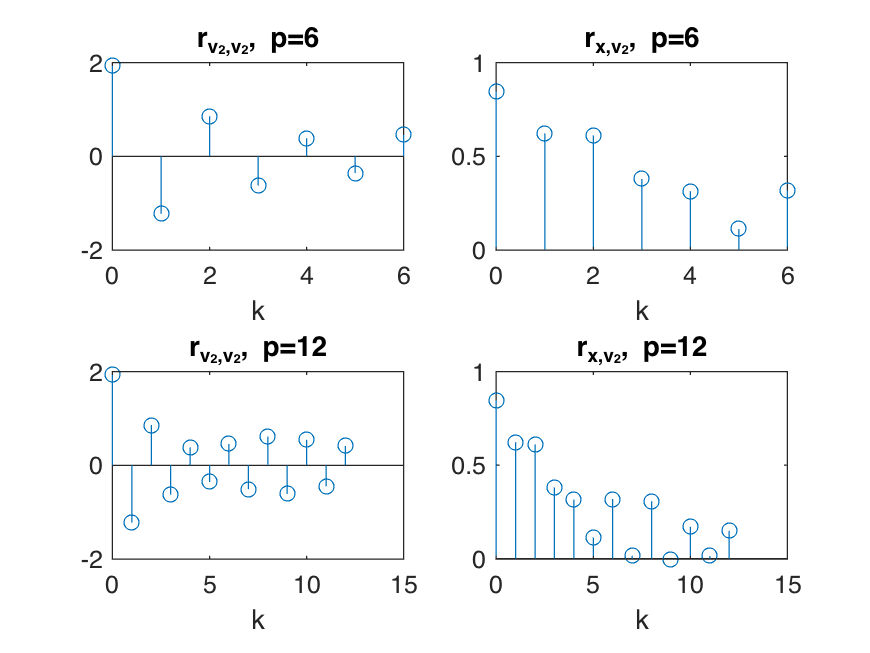

% full autocorrelation r_v2_v2
[r_v2_v2_p1, lag_6] = xcorr(v2, v2', p(1), 'biased');
[r_v2_v2_p2, lag_12] = xcorr(v2, v2', p(2), 'biased');
% full cross-correlation r_x_v2
[r_x_v2_p1, ~] = xcorr(xn, v2', p(1), 'biased');
[r_x_v2_p2, ~] = xcorr(xn, v2', p(2), 'biased');

% take only the half and make it vertical
r_v2_v2_p1 = r_v2_v2_p1(p(1)+1:end)';
r_v2_v2_p2 = r_v2_v2_p2(p(2)+1:end)';
r_x_v2_p1  = r_x_v2_p1(p(1)+1:end)';
r_x_v2_p2  = r_x_v2_p2(p(2)+1:end)';
lag_6  = lag_6(p(1)+1:end)';
lag_12 = lag_12(p(2)+1:end)';

% autocorrelation matrices
R_v2_v2_p1 = toeplitz(r_v2_v2_p1, r_v2_v2_p1);
R_v2_v2_p2 = toeplitz(r_v2_v2_p2, r_v2_v2_p2);

figure;
subplot(2,2,1);
    stem(lag_6, r_v2_v2_p1);
    title(['r_{v_2,v_2}, p=', num2str(p(1))]);
    xlabel('k');
subplot(2,2,2);
    stem(lag_6, r_x_v2_p1);
    title(['r_{x,v_2}, p=', num2str(p(1))]);
    xlabel('k');
subplot(2,2,3);
    stem(lag_12, r_v2_v2_p2);
    title(['r_{v_2,v_2}, p=', num2str(p(2))]);
    xlabel('k');
subplot(2,2,4);
    stem(lag_12, r_x_v2_p2);
    title(['r_{x,v_2}, p=', num2str(p(2))]);
    xlabel('k');

The Wiener coefficients obtained are:

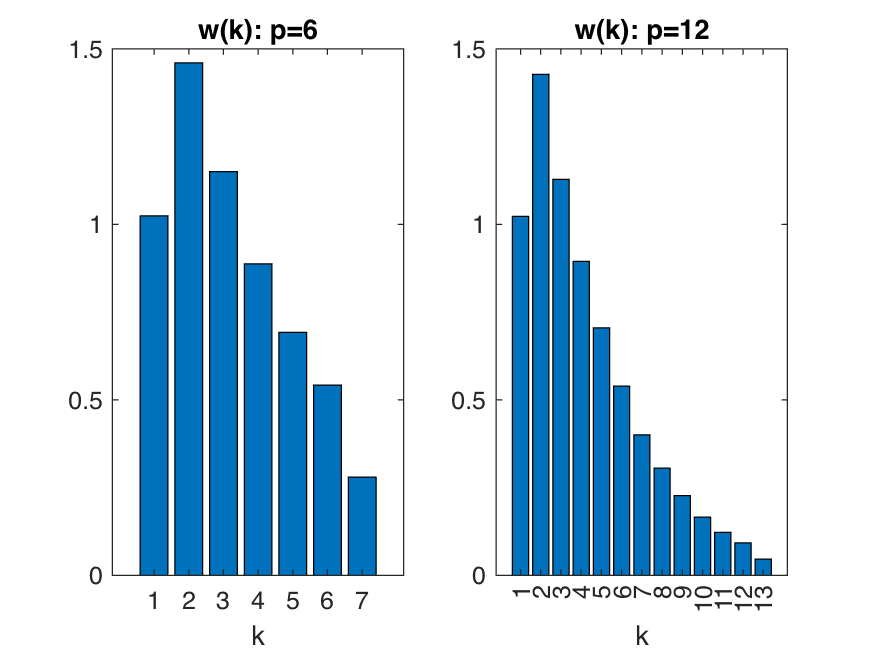

% compute Wiener coefficients
W_p1 = R_v2_v2_p1\r_x_v2_p1;
W_p2 = R_v2_v2_p2\r_x_v2_p2;

figure;
subplot(1,2,1);
    bar(W_p1);
    title(['w(k): p=' num2str(p(1))]);
    xlabel('k');
subplot(1,2,2);
    bar(W_p2);
    title(['w(k): p=' num2str(p(2))]);
    xlabel('k');

### filtering

Estimate the noise v1 based on v2 and the Wiener filter designed

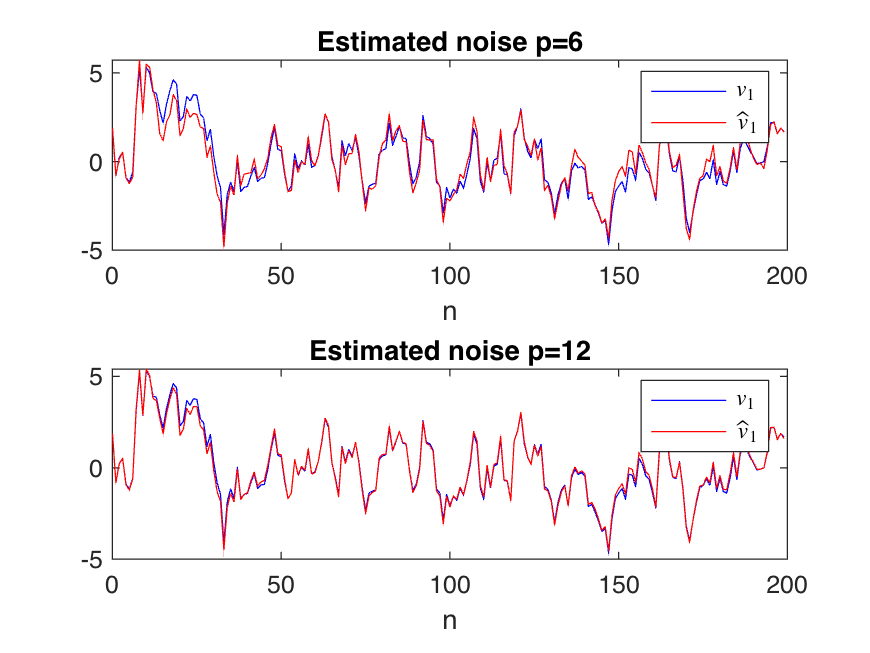

%disp(['With p=' num2str(p(1)), ', W(z)=']); printsys(W_p1', [zeros(1, p(1)), 1], 'z');
%disp(['With p=' num2str(p(2)), ', W(z)=']); printsys(W_p2', [zeros(1, p(2)), 1], 'z');
v1_hat_p1 = filter(W_p1, 1, v2);
v1_hat_p2 = filter(W_p2, 1, v2);

% import v1 to compare (in reality we don't know it)
v1 = importedData.v1;

figure;
subplot(2,1,1);
    plot(n, v1, 'b', ...
         n, v1_hat_p1, 'r');
    title(['Estimated noise p=' num2str(p(1))]);
    xlabel('n');
    legend('$v_1$', '$\hat{v}_1$','Interpreter','latex');
subplot(2,1,2);
    plot(n, v1, 'b', ...
         n, v1_hat_p2, 'r');
    title(['Estimated noise p=' num2str(p(2))]);
    xlabel('n');
    legend('$v_1$', '$\hat{v}_1$','Interpreter','latex');

Finally, the estimated noise can be removed from the measured signal.

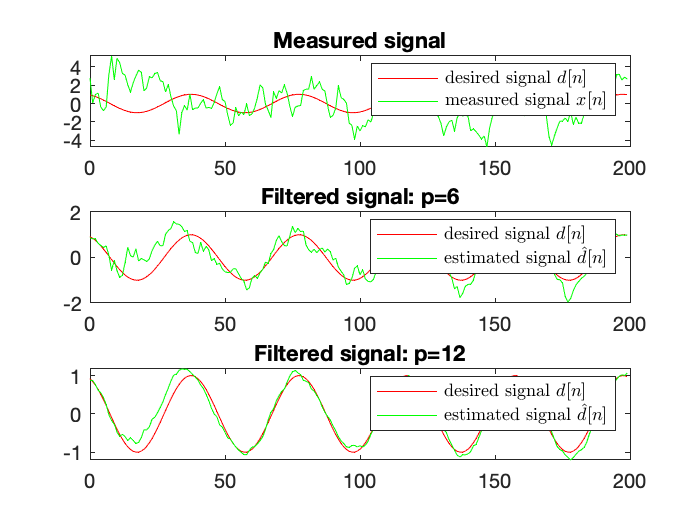

figure;
subplot(3,1,1);
    plot(n, dn, 'r', ...
         n, xn, 'g');
    title('Measured signal');
    legend('desired signal $d[n]$', 'measured signal $x[n]$', 'Interpreter', 'latex');
subplot(3,1,2);
    plot(n, dn, 'r', ...
         n, xn-v1_hat_p1, 'g');
    title(['Filtered signal: p=' num2str(p(1))]);
    legend('desired signal $d[n]$', 'estimated signal $\hat{d}[n]$', 'Interpreter', 'latex');
subplot(3,1,3);
    plot(n, dn, 'r', ...
         n, xn-v1_hat_p2, 'g');
    title(['Filtered signal: p=' num2str(p(2))]);
    legend('desired signal $d[n]$', 'estimated signal $\hat{d}[n]$', 'Interpreter', 'latex');

And the error on the signal reconstruction can be computed:

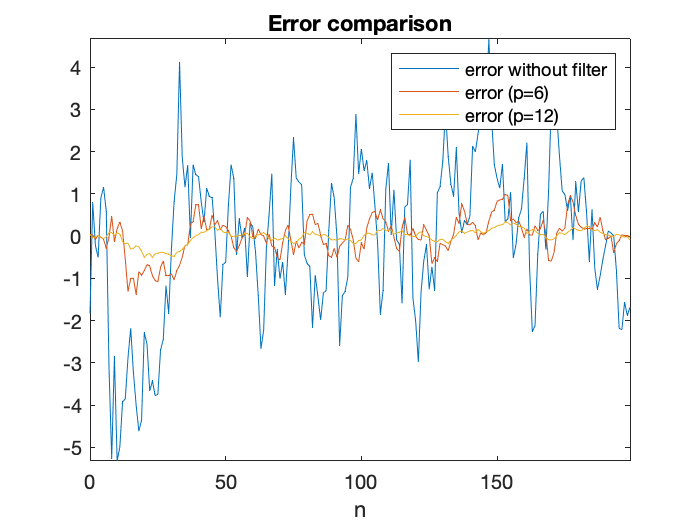

en_p0 = dn-xn;              % error without filter
en_p1 = dn-(xn-v1_hat_p1);  % error with filter p(1)
en_p2 = dn-(xn-v1_hat_p2);  % error with filter p(2)

figure;
    plot(n, en_p0, ...
         n, en_p1, ...
         n, en_p2);
    title('Error comparison');
    legend('error without filter', ['error (p=' num2str(p(1)) ')'], ['error (p=' num2str(p(2)) ')']);
    xlabel('n');
    axis tight

    %xlim([0 N-1]);